# Projektovanje kontrolera na bazi inverzije dinamike za pracenje reference

clc;
close all;
clear variables;

[out_dummy, G, A, B, H, ue] = evalc('linearizacija'); % Poziv f-je linearizacija sa potisnutim ispisom
[L, R, C, E, x2e] = nominalni_parametri();
s = tf('s');

## Inverzija dinamike na bazi pracenja reference

G

G =
 
      2646.8 (s-606.3)
  -------------------------
  (s^2 + 40.92s + 1.618e04)
 
Continuous-time zero/pole/gain model.



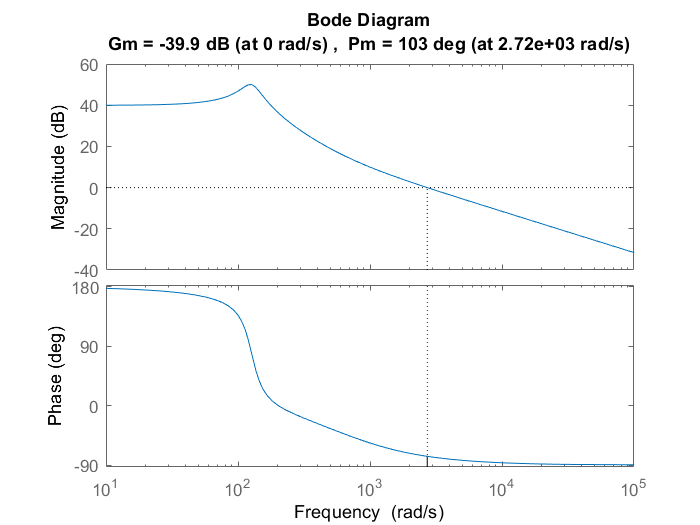

figure()
margin(G)

[w_z, gain] = zero(G);
poles = pole(G);
w_ogranicenje = w_z/4;
G_approx = zpk(-w_z, poles, gain)

G_approx =
 
      2646.8 (s+606.3)
  -------------------------
  (s^2 + 40.92s + 1.618e04)
 
Continuous-time zero/pole/gain model.



w1 = w_ogranicenje

w1 = 151.5773

K = -w1/s * G_approx^(-1)

K =
 
  -0.057268 (s^2 + 40.92s + 1.618e04)
  -----------------------------------
              s (s+606.3)
 
Continuous-time zero/pole/gain model.



W = minreal(K*G)

W =
 
  -151.58 (s-606.3)
  -----------------
     s (s+606.3)
 
Continuous-time zero/pole/gain model.



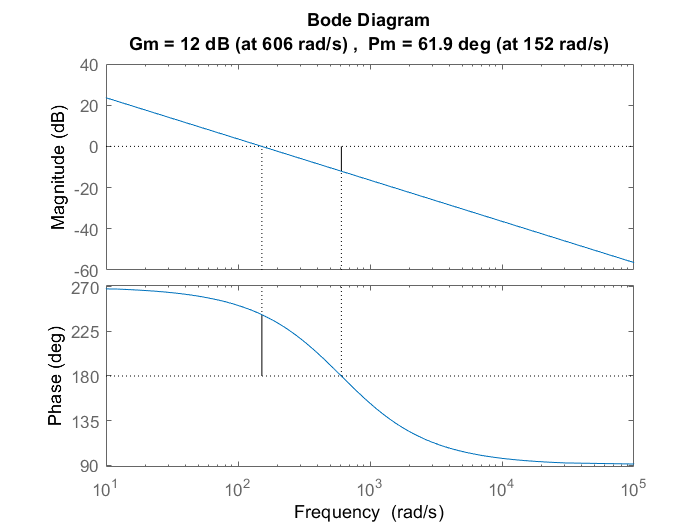

figure()
margin(W)

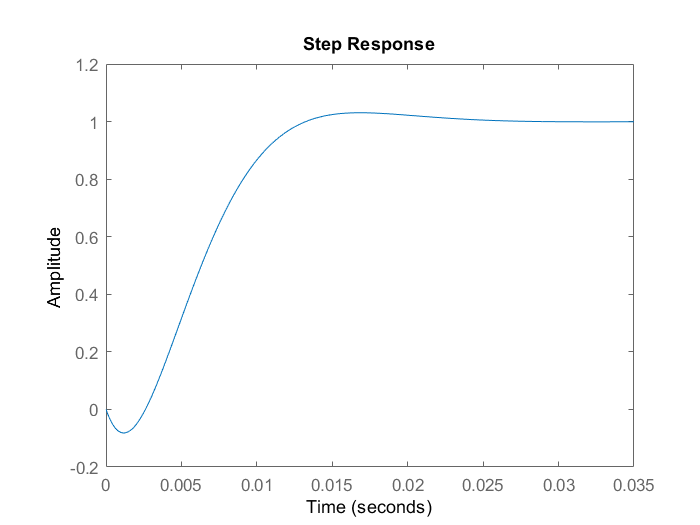

figure()
step(W/(W + 1))

[k_num, k_den] = tfdata(K, 'v');

## Simulacija

sim_duration = 5; % sec
sim_file_name = 'buck_boost_sim'; 
open_system(sim_file_name) 
out = sim(sim_file_name);